# Unit 4.3: Fourier Transforms for Circuit and LTI Systems Analysis

Prepared for EG-247 Digital Signal Processing by Dr C.P. Jobling

## Example 1

Karris example 8.8: for the linear network shown below, the impulse response is $h(t) = 3e^{-2t}u_0(t)$. Use the Fourier transform to compute the response $y(t)$ when the input $u(t)=2\left[u_0(𝑡)-u_0(𝑡-3)\right]$. Verify the result with MATLAB.

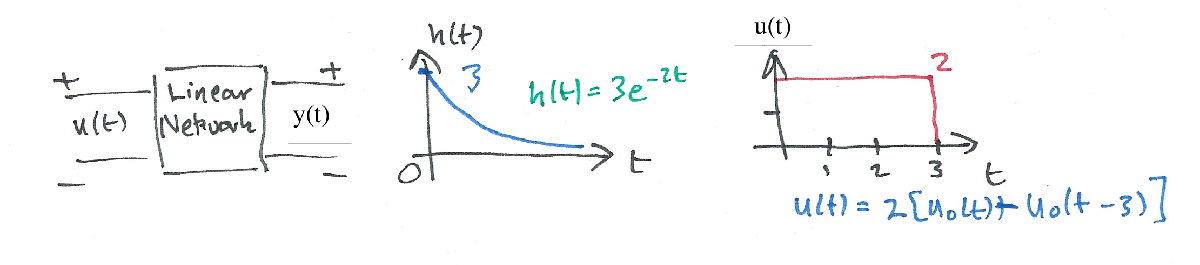

Worked solution: [ft3-ex1.pdf](https://cpjobling.github.io/eg-247-textbook/fourier_transform/solutions/ft3-ex1.pdf)

### Set up the problem

syms t w

### Set up the signal

U1 = fourier(2*heaviside(t),t,w)

$$U1 = 2\,\pi \,\delta (w)-\frac{2\,\mathrm{i}}{w}$$

### Set up the system function

H = fourier(3*exp(-2*t)*heaviside(t),t,w)

$$H = \frac{3}{2+w\,\mathrm{i}}$$

### Compute the system response

Y1=simplify(H*U1)

$$Y1 = 3\,\pi \,\delta (w)-\frac{6\,\mathrm{i}}{w\,\left(2+w\,\mathrm{i}\right)}$$

y1 = simplify(ifourier(Y1,w,t))

$$y1 = \frac{3\,{\mathrm{e}}^{-2\,t}\,\left(\mathrm{sign}\left(t\right)+1\right)\,\left({\mathrm{e}}^{2\,t}-1\right)}{2}$$

### Get y2

substitute t-3 into t.

y2 = subs(y1,t,t-3)

$$y2 = \frac{3\,{\mathrm{e}}^{6-2\,t}\,\left(\mathrm{sign}\left(t-3\right)+1\right)\,\left({\mathrm{e}}^{2\,t-6}-1\right)}{2}$$

y = y1 - y2

$$y = \frac{3\,{\mathrm{e}}^{-2\,t}\,\left(\mathrm{sign}\left(t\right)+1\right)\,\left({\mathrm{e}}^{2\,t}-1\right)}{2}-\frac{3\,{\mathrm{e}}^{6-2\,t}\,\left(\mathrm{sign}\left(t-3\right)+1\right)\,\left({\mathrm{e}}^{2\,t-6}-1\right)}{2}$$

### Plot result

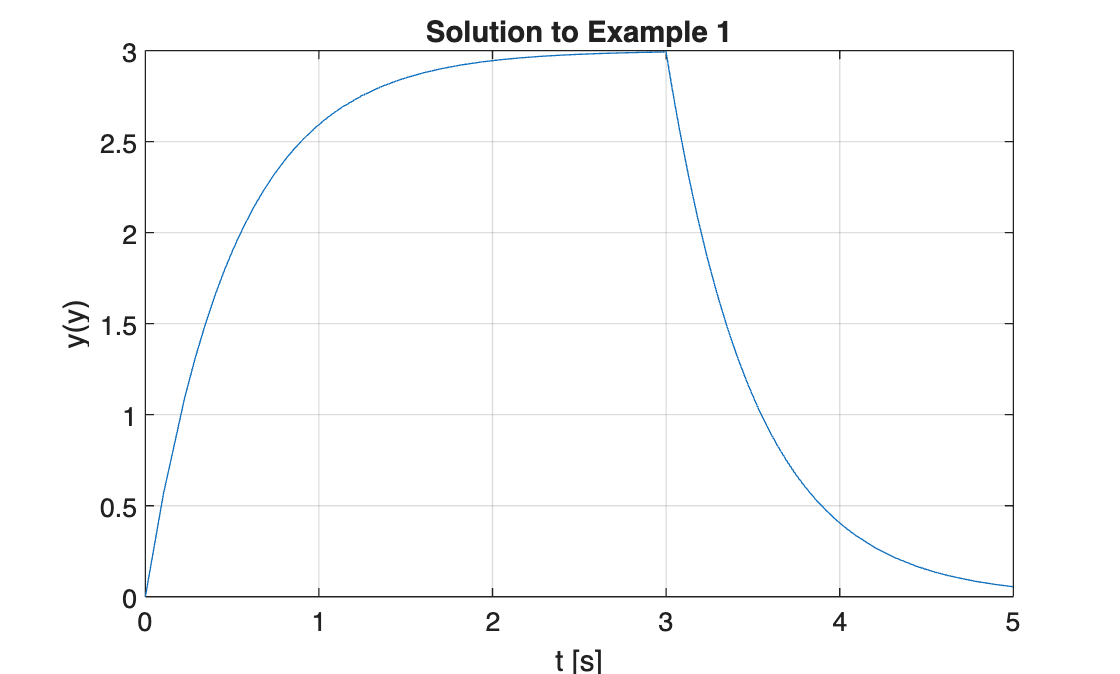

fplot(y,[0,5])
title('Solution to Example 1')
ylabel('y(y)')
xlabel('t [s]')
grid